Task: Median Filtering 

Description: In image processing, median filtering is a common nonlinear filtering technique used to remove noise and preserve edges in an image. The median filter replaces each pixel value with the median value of its neighboring pixels. In this task, you will apply the median filter to a given image and analyze the results.

Instructions:

- Load the image 'brain.jpg' 

- Add Gaussian noise to the image using the 'imnoise' function. Use the 'gaussian' noise type and specify a mean of 0 and a variance of your choice (e.g., 0.1). 

- Display the original image and the noisy image.

- Convert the image to double. Apply a median filter to the image using a filter size of 3x3 (use 'medfilt2' function). Display the filtered image using the `imshow` function.

- Compute the median value of the original image and the filtered image using the median function.

- Compute and display the enhanced difference image, use 'imadjust' to enhanced the image, also add a colormap.

- Sort the pixels within the neighborhood defined by the structuring element and display the sorted image (use 'ordfilt2').

- Compute and display the median image

- Compare the median values and describe the effect of the median filter on the image.

- Discuss the advantages and limitations of using the median filter for image filtering.

- Optional: Experiment with different filter sizes (e.g., 5x5, 7x7) and observe the changes in the filtered image.

MATLAB code - solution:

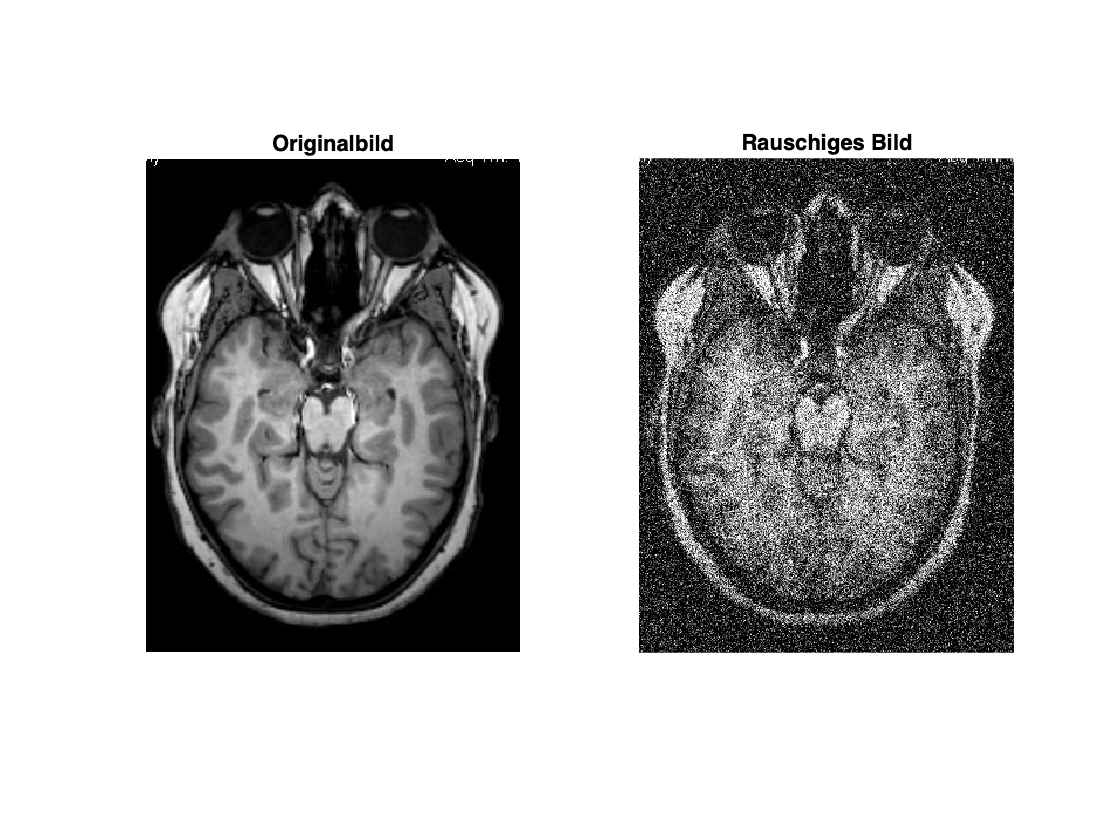

% Task: Median Filtering

% 1. Laden des Bildes
image = imread('brain.jpg');

% 2. Hinzufügen von Rauschen zum Bild
noisyImage = imnoise(image, 'gaussian', 0, 0.1);

% 3. Anzeigen des Originalbildes und des rauschigen Bildes
figure;
subplot(1, 2, 1);
imshow(image);
title('Originalbild');

subplot(1, 2, 2);
imshow(noisyImage);
title('Rauschiges Bild');

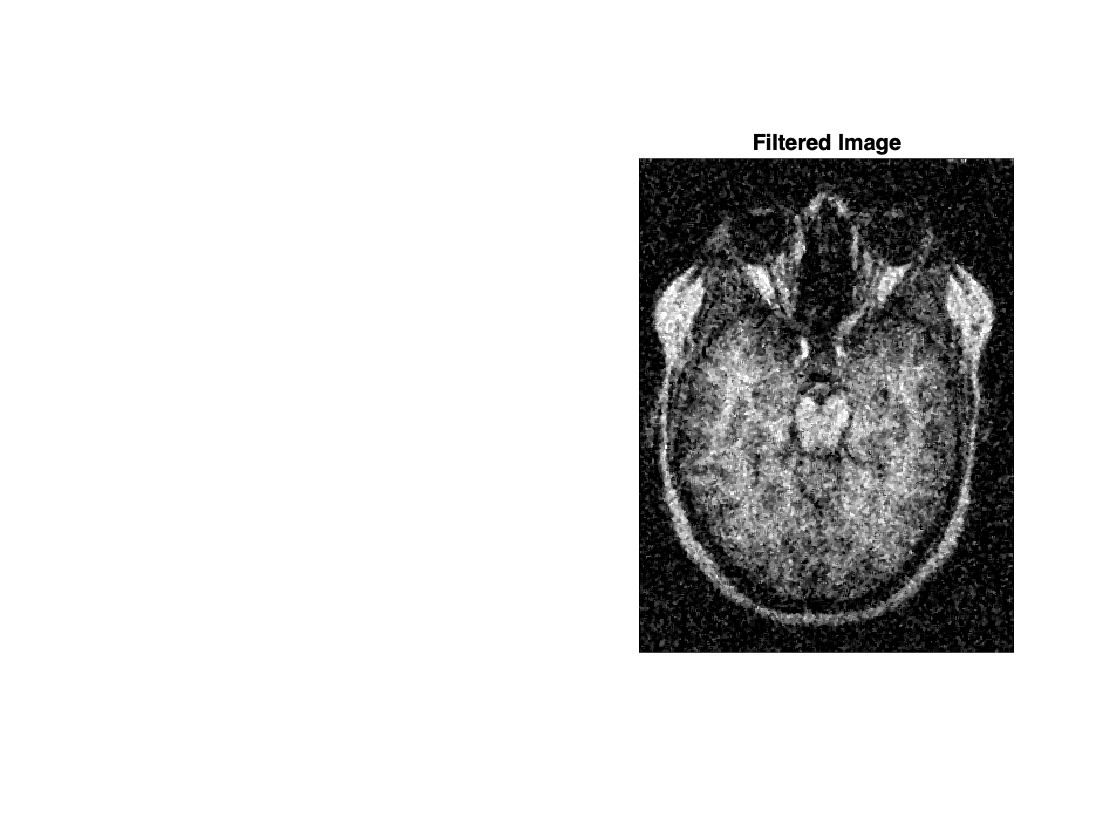

% 4. Convert the image
image = im2double(noisyImage(:,:,1)); % Das Bild wird in ein Fließkommabild konvertiert

% 4. Apply a median filter and display the filtered image
filteredImage = applyMedianFilter(image, [3 3]); % Ein Medianfilter mit einer Filtergröße von 3x3 wird angewendet

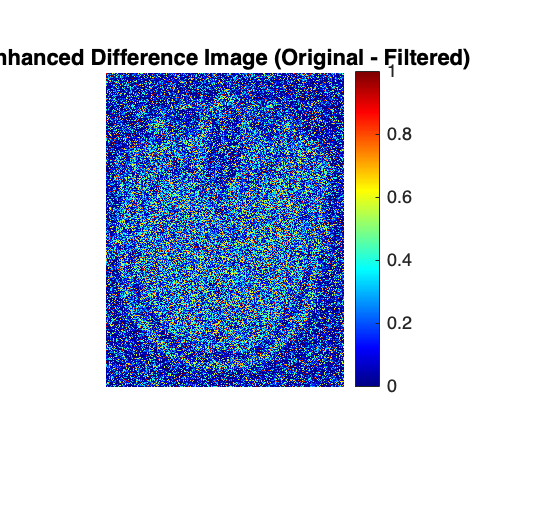

% Das Ergebnis des Filters wird in der Variable "filteredImage" gespeichert
% Die Funktion wird ausgelagert, um den Code übersichtlicher zu gestalten

% 5. Compute the median values
originalMedian = median(image(:)); % Der Medianwert des Originalbildes wird berechnet
filteredMedian = median(filteredImage(:)); % Der Medianwert des gefilterten Bildes wird berechnet

% 6. Compute and display the enhanced difference image
enhancedDiffImage = enhanceDifferenceImage(image, filteredImage); % Das Differenzbild zwischen dem Originalbild und dem gefilterten Bild wird berechnet und verstärkt

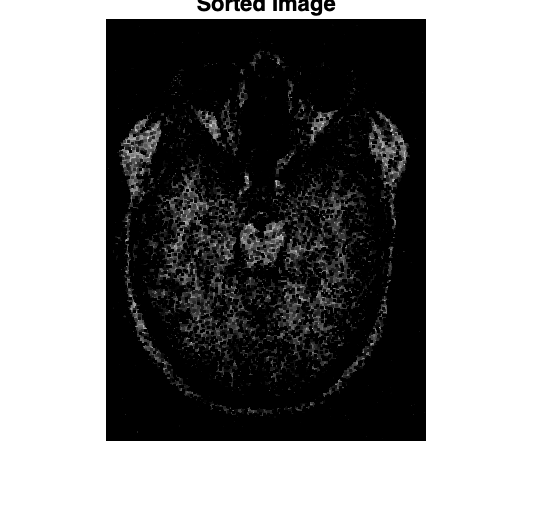


% 7. Sort the pixels within the neighborhood defined by the structuring element and display the sorted image
sortedImage = sortImage(image, [3 3]);
figure;
imshow(sortedImage);
title('Sorted Image');

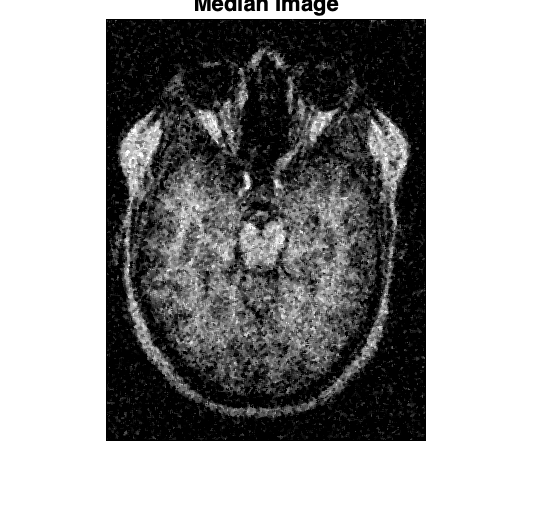


% 8. Compute and display the median image
medianImage = medianFilterImage(image, [3 3]);
figure;
imshow(medianImage);
title('Median Image');


% 9. Compare the median values and describe the effect
fprintf('Median of the original image: %d\n', originalMedian); % Der Medianwert des Originalbildes wird ausgegeben

Median of the original image: 2.313725e-01


fprintf('Median of the filtered image: %d\n', filteredMedian); % Der Medianwert des gefilterten Bildes wird ausgegeben

Median of the filtered image: 2.000000e-01



% 10. Discuss the advantages and limitations
displayAdvantagesAndLimitations(); % Die Vor- und Nachteile des Medianfilters werden ausgegeben

The median filter helps in reducing noise while preserving edges in the image.
It replaces each pixel value with the median value of its neighborhood.
Advantages: Good at removing salt-and-pepper noise, preserves edges.
Limitations: Can blur fine details, not effective for removing Gaussian noise.


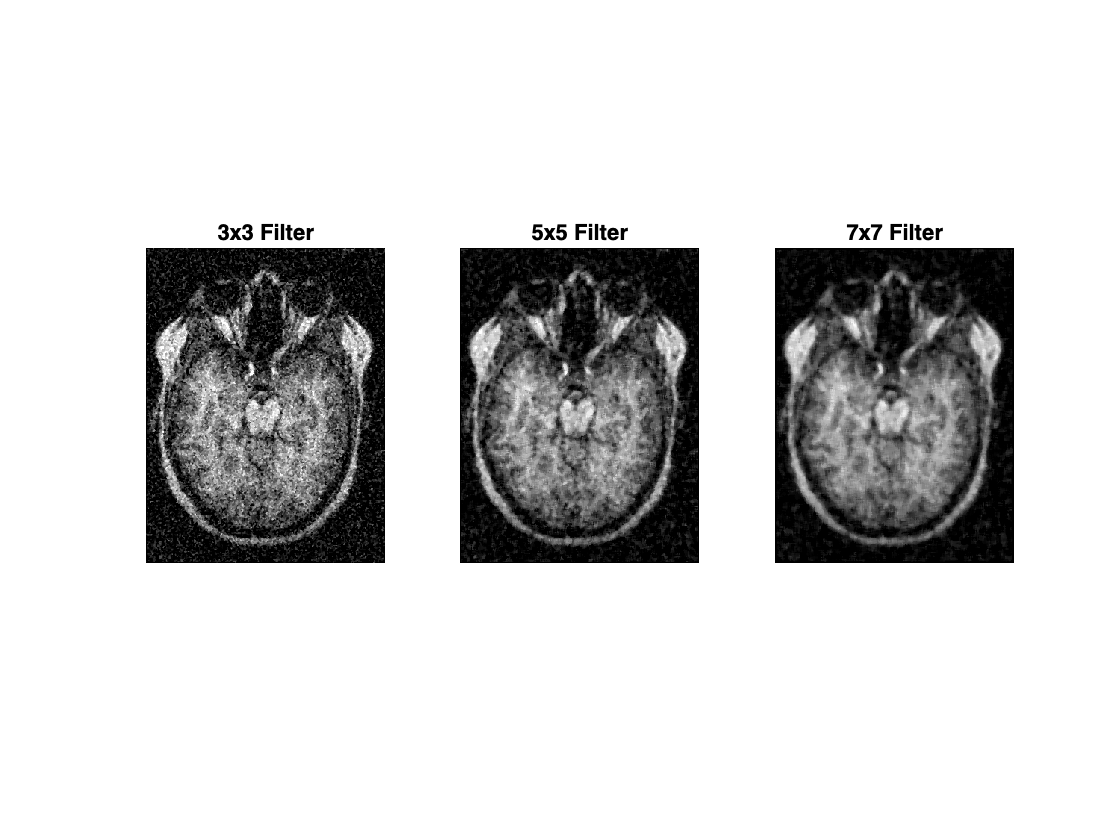


% 11. Optional: Experiment with different filter sizes
filteredImage2 = medfilt2(image, [5 5]); % Ein Medianfilter mit einer Filtergröße von 5x5 wird angewendet
filteredImage3 = medfilt2(image, [7 7]); % Ein Medianfilter mit einer Filtergröße von 7x7 wird angewendet

figure;
subplot(1, 3, 1);
imshow(filteredImage);
title('3x3 Filter');

subplot(1, 3, 2);
imshow(filteredImage2);
title('5x5 Filter');

subplot(1, 3, 3);
imshow(filteredImage3);
title('7x7 Filter');


% Function to apply a median filter

function filteredImage = applyMedianFilter(image, filterSize)
    filteredImage = medfilt2(image, filterSize); % Die Funktion "medfilt2" wird verwendet, um den Medianfilter anzuwenden
    figure;
    subplot(1, 2, 2);
    imshow(filteredImage);
    title('Filtered Image');
end

% Function to compute and enhance the difference image
function enhancedDiffImage = enhanceDifferenceImage(image, filteredImage)
    diffImage = abs(image - filteredImage); % Das Differenzbild zwischen dem Originalbild und dem gefilterten Bild wird berechnet
    enhancedDiffImage = imadjust(diffImage); % Das Differenzbild wird verbessert
    figure;
    imshow(enhancedDiffImage, []);
    title('Enhanced Difference Image (Original - Filtered)');
    colormap jet;
    colorbar;
end

% Function to sort the pixels within the neighborhood
function sortedImage = sortImage(image, neighborhoodSize)
    sortedImage = ordfilt2(image, 1, ones(neighborhoodSize));
    % Die Funktion ordfilt2 wendet die Ordnungsstatistik auf das Bild an.
    % Mit dem Parameter 1 wird der kleinste Wert in der Nachbarschaft ausgewählt.
    % Die Größe der Nachbarschaft wird durch das neighborhoodSize-Argument angegeben.
end

% Function to compute the median image
function medianImage = medianFilterImage(image, neighborhoodSize)
    medianImage = ordfilt2(image, floor(prod(neighborhoodSize)/2), ones(neighborhoodSize));
    % Mit dem Parameter floor(prod(neighborhoodSize)/2) wird der Medianwert in der Nachbarschaft ausgewählt.
    % Die Größe der Nachbarschaft wird durch das neighborhoodSize-Argument angegeben.
    % Die floor-Funktion wird verwendet, um sicherzustellen, dass der Index für den Medianwert ganzzahlig ist.
end

% Function to display advantages and limitations
function displayAdvantagesAndLimitations()
    disp('The median filter helps in reducing noise while preserving edges in the image.');
    disp('It replaces each pixel value with the median value of its neighborhood.');
    disp('Advantages: Good at removing salt-and-pepper noise, preserves edges.');
    disp('Limitations: Can blur fine details, not effective for removing Gaussian noise.');
end